clc
clear

% Import the data from .csv file
[t, toy, p, Ws1, Wd1, T1, Ws2, Wd2, T2, Ws3, Wd3, T3] = ...
    importfile('cex4WindDataInterpolated.csv');

% Keep only valid power data
index=find(~isnan(p));
idx=find(diff(index)~=1);
A=[idx(1);diff(idx);numel(index)-idx(end)];
power=mat2cell(p(~isnan(p)),A,1);
celldisp(power)

 
power{1} =
 
    1.2670
    1.5150
    1.9150
    1.6130
    1.7760
    1.9980
    1.8450
    0.9640
    0.6460
    2.7600
    1.8410
    1.5590
    1.0110
    2.6960
    3.0210
    1.8730
    4.6180
    5.1190
    2.3280
    1.4920
    4.1310
    7.6110
    8.3310
    9.2640
    8.1520
    7.7700
    6.8360
    4.6130
    6.7640
    5.8380
    5.8070
    4.1490
    3.6940
    4.1290
    4.6740
    5.6850
    5.4050
    8.6860
    8.2680
    9.4920
   11.3880
    9.3560
    9.3590
    9.8430
   10.6550
   10.5890
   11.5360
   10.6010
    9.3680
   10.8680
    8.5050
    8.3030
    9.8700
    6.3750
    5.4740
    5.3600
    4.8520
    4.2490
    4.6860
    3.6510
    1.6010
    1.4710
    2.1910
    2.9240
    2.8950
    4.0340
    6.2520
    5.4990
    5.9010
    6.7930
    4.2680
    2.2260
    4.7940
    3.0510
    4.5520
    6.8940
    9.5110
   11.9260
   13.2300
   16.0650
   18.4040
   19.5100
   19.7880
   15.2210
   13.5690
   14.7710
   16.7590
   16.5120
   20.1900
   20.

## Fit an ARMA model to p

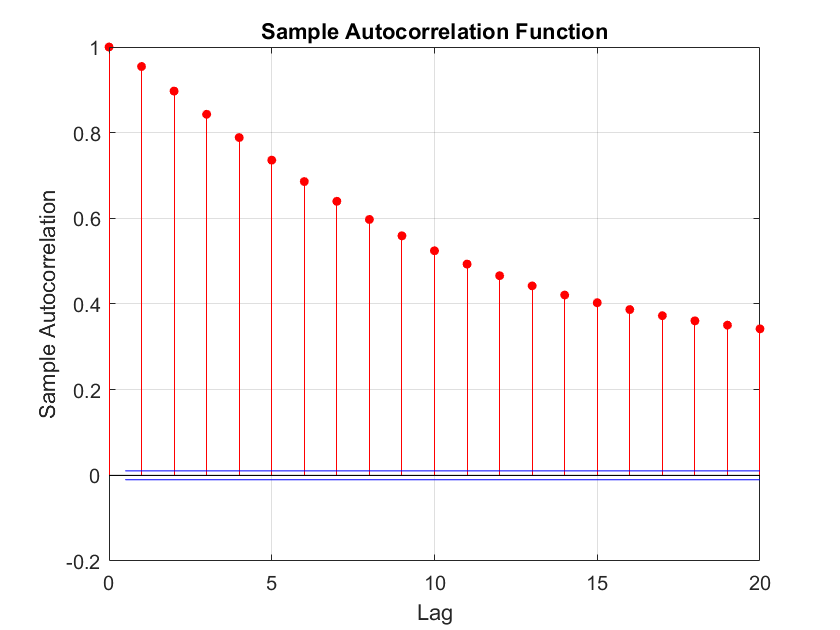

% Plot ACF and PACF
figure(1)
autocorr(p)

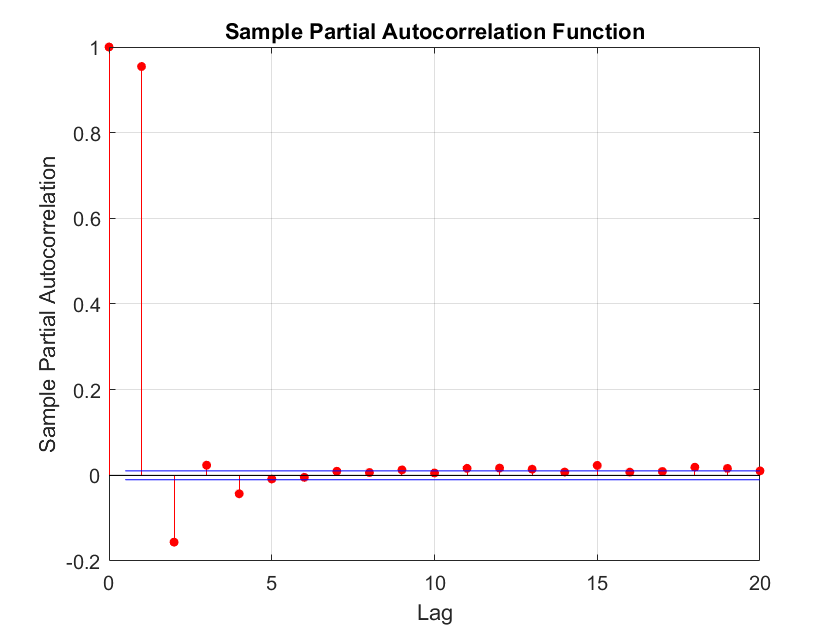


figure(2)
parcorr(p)

**Test directly a seasonal ARIMA**

% Test an AR(4)(1)24
Md2 = arima('ARLags',[1:24]);%,'Seasonality',24,'SMALags',24)%,'Seasonality',24,'SMALags',24);
EstMd2 = estimate(Md2,p)

 
    ARIMA(24,0,0) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic      PValue  
                ___________    _____________    __________    __________

    Constant        0.22671       0.019181         11.819     3.1017e-32
    AR{1}             1.105      0.0033983         325.17              0
    AR{2}          -0.18862      0.0046524        -40.543              0
    AR{3}          0.070319      0.0051372         13.688     1.1939e-42
    AR{4}          -0.03465      0.0053263        -6.5053      7.752e-11
    AR{5}       -0.00065879      0.0055384       -0.11895        0.90532
    AR{6}         -0.014307      0.0053976        -2.6506      0.0080359
    AR{7}        

EstMd2 =   arima with properties:

     Description: "ARIMA(24,0,0) Model (Gaussian Distribution)"
    Distribution: Name = "Gaussian"
               P: 24
               D: 0
               Q: 0
        Constant: 0.226709
              AR: {1.10502 -0.188621 0.0703195 -0.0346496 -0.000658792 -0.0143067 0.00368197 -0.004597 0.00697533 -0.00947163 0.00212103 -0.000359497 0.0110667 -0.0170053 0.016753 -7.96953e-05 -0.0108747 0.00415344 0.00514653 0.00498873 0.00386558 0.012718 -0.00737898 -0.00495745} at lags [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24]
             SAR: {}
              MA: {}
             SMA: {}
     Seasonality: 0
            Beta: [1×0]
        Variance: 2.60658

summarize(EstMd2)

 
   ARIMA(24,0,0) Model (Gaussian Distribution)
 
    Effective Sample Size: 37583
    Number of Estimated Parameters: 26
    LogLikelihood: -71333.7
    AIC: 142719
    BIC: 142941
 
                   Value       StandardError    TStatistic      PValue  
                ___________    _____________    __________    __________

    Constant        0.22671       0.019181         11.819     3.1017e-32
    AR{1}             1.105      0.0033983         325.17              0
    AR{2}          -0.18862      0.0046524        -40.543              0
    AR{3}          0.070319      0.0051372         13.688     1.1939e-42
    AR{4}          -0.03465      0.0053263        -6.5053      7.752e-11
    AR{5}       -0.00065879      0.0055384      

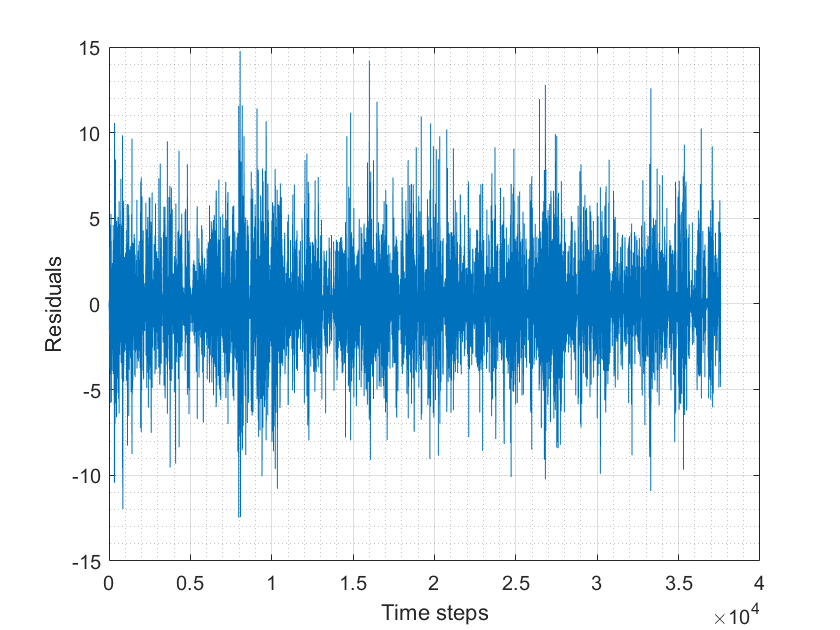

% Compute the residuals
[res2, R] = infer(EstMd2,p);
plot(res2)
grid on; grid minor;
xlabel('Time steps')
ylabel('Residuals')


% Ljung-Box test
[h,pvalues]=lbqtest(res2,'lags',[1:50])

h = 1×50 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


pvalues =     0.9045    0.9920    0.9991    0.9974    0.9995    0.9925    0.9970    0.9989    0.9997    0.9997    0.9989    0.9995    0.9998    0.9997    0.9998    0.9999    1.0000    1.0000    1.0000    1.0000    0.9999    0.9999    0.9996    0.9997    0.9998    0.9980    0.9985    0.9988    0.9986    0.9984    0.9989    0.9993    0.9988    0.9988    0.9926    0.9942    0.9946    0.9956    0.9967    0.9966    0.9954    0.9918    0.9895    0.9904    0.9791    0.9389    0.9417    0.9243    0.8858    0.9014


% Validation of the hypothesis that the residuals are not correlated

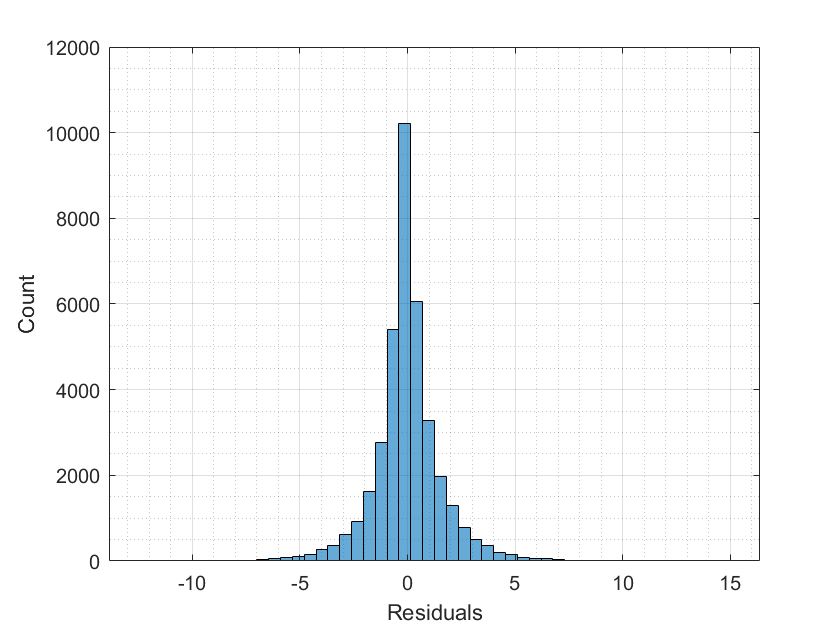

%Histogram of residuals
histogram(res2,50)
grid on; grid minor;
xlabel('Residuals')
ylabel('Count')

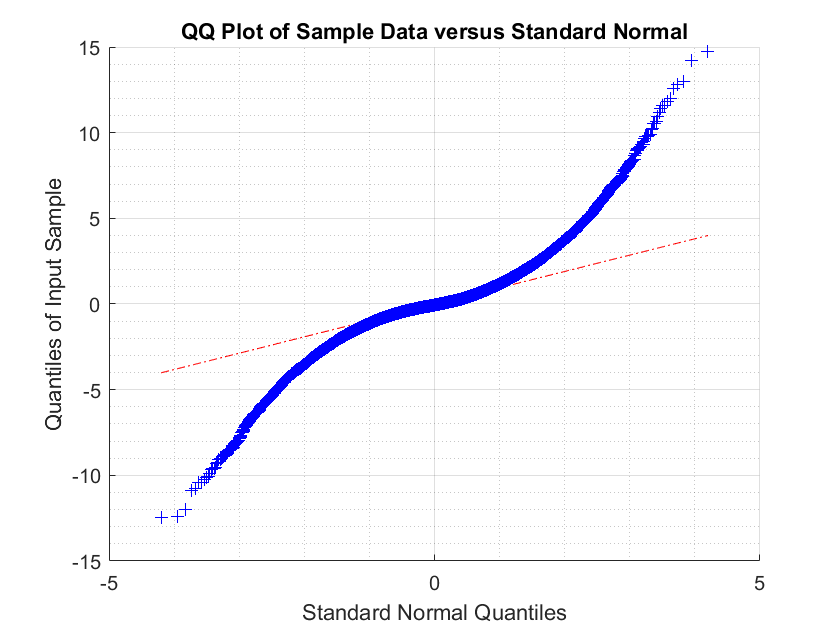


%QQ plot
qqplot(res2)
grid on; grid minor;

% Sign test
count=0;
for i=1:length(res2)-1
    if sign(res2(i)) == sign(res2(i+1))
        count = count+1;
    end
end
percent_sign_change = count/length(res2)

percent_sign_change = 0.5518


%The test sign is conclusive

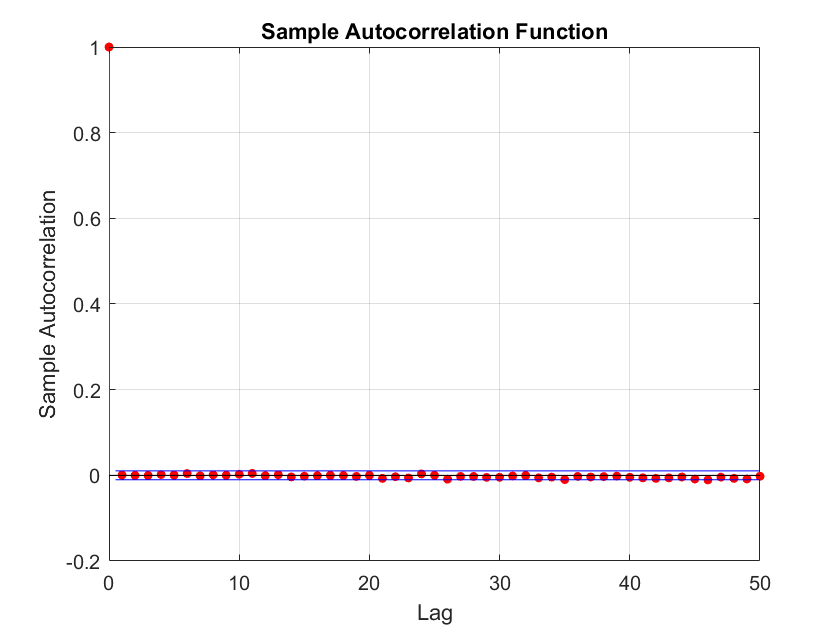

% ACF and PACF of the residuals
autocorr(res2,'NumLags',50)

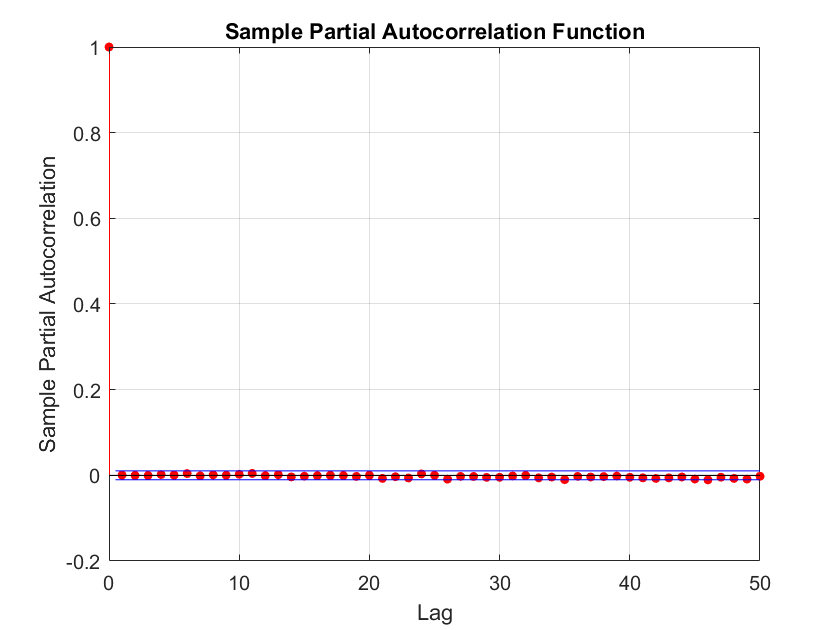

parcorr(res2,'NumLags',50)

**Looking at the ACF and PACF of the residuals it is clear that adding the seasonality does not have the expected effect. Instead of eliminating the correlations at lag 24 and 48, it created ones. **

**We may therefore stay for now with the simple AR(4) model.**

## **Predictions 1, 2 and 3 hours ahead with AR(4)x(24)s**

% compute the errors of prediction
error = zeros(length(power{1})-7,3);
for i=4:length(power{1})-3
    % Prediction 3h ahead given past data
    error(i-3,:) = forecast(EstMd2,3,power{1}) - power{1}(i+1:i+3);
    if mod(i,400)==0
        X = sprintf('Compute %d%%',round(100*i/(length(power{1})-7)));
        disp(X)
    end
end

Compute 5%
Compute 10%
Compute 15%
Compute 20%
Compute 24%
Compute 29%
Compute 34%
Compute 39%
Compute 44%
Compute 49%
Compute 54%
Compute 59%
Compute 64%
Compute 68%
Compute 73%
Compute 78%
Compute 83%
Compute 88%
Compute 93%
Compute 98%


% RMSE for each step ahead
RMSE_1h = sqrt(mean(error(:,1).^2))

RMSE_1h = 5.8338

RMSE_2h = sqrt(mean(error(:,2).^2))

RMSE_2h = 6.6748

RMSE_3h = sqrt(mean(error(:,3).^2))

RMSE_3h = 6.5844


% 95% confidence intervals
CI_1h = [RMSE_1h*norminv(0.025),RMSE_1h*norminv(0.975)]

CI_1h =   -11.4340   11.4340


CI_2h = [RMSE_2h*norminv(0.025),RMSE_2h*norminv(0.975)]

CI_2h =   -13.0824   13.0824


CI_3h = [RMSE_3h*norminv(0.025),RMSE_3h*norminv(0.975)]

CI_3h =   -12.9052   12.9052
